# Processing Data Samples from MRI

Reference - J. Appl. Phys. 105, 004904  (2009)

## 1. Create New Material (Estimate the Response of a Material)

n - Cole Cole Dispersions frequencies (Water has 2)

[http://vosykazoran.weebly.com/uploads/1/2/4/5/12453032/cole_cole_1941.pdf](http://vosykazoran.weebly.com/uploads/1/2/4/5/12453032/cole_cole_1941.pdf)

Time Constant Values 

[http://www.m-hikari.com/astp/astp2008/astp13-16-2008/thakurASTP13-16-2008.pdf](http://www.m-hikari.com/astp/astp2008/astp13-16-2008/thakurASTP13-16-2008.pdf)

Electrical Properties of tissues

[http://andrewamarino.com/PDFs/MB/MB_Ch06.pdf](http://andrewamarino.com/PDFs/MB/MB_Ch06.pdf)

**Cole Cole Dispersions**


$$\varepsilon \left(\omega \right)=\varepsilon_{\infty } +\sum_{m=1}^{n} \frac{\Delta \varepsilon_m }{1+{\left(j\omega \tau_m \right)}^{\left(1-\alpha_m \right)} }+\frac{\sigma_i }{j\omega \varepsilon_0 }$$


clear; clc;

% Physics Values and Name of Material
name = 'Water (Pure)';
p_inf = 4.44;           % Permittivity at infinite frequency (Water)
temp = 25;              % Temperature

% First Debye Relaxation (Water)
p_del(1) = 80.1 - 4.44; % Permittivity at zero frequency (Water)
t_const(1) = 9.4e-12;   % Debye Relaxation Frequency
a(1) = 0.0120;          % Dispersion Coefficient
con(1) = 0;             % Conductivity

% Second Debye Relaxation (Optional) Use (2) for sescond debye relaxation

freq = logspace(8,11);
e_w = create_material(p_inf, p_del, t_const, a, con);
save(strcat('materials/', name, '.mat'));

hold on;

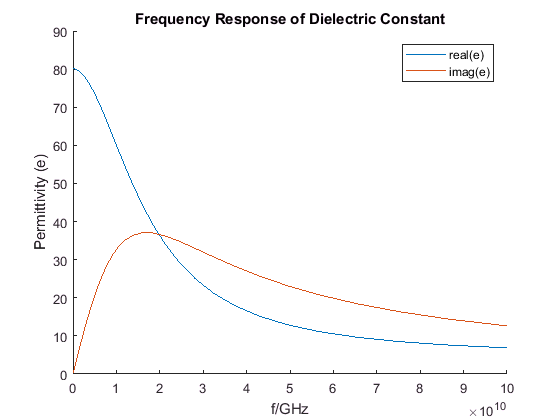

semilogx(freq, real(e_w));
semilogx(freq, abs(imag(e_w)));
title('Frequency Response of Dielectric Constant')
xlabel('f/GHz')
ylabel('Permittivity (e)')
legend({'real(e)','imag(e)'})
hold off;


clear

## 2. Analyze Created Material (From DielectricDatabase.mat)

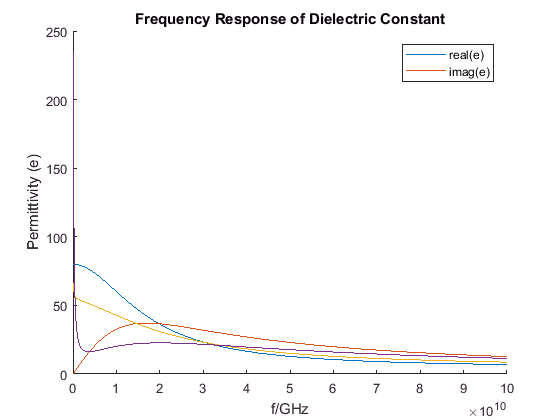

% Obtain the material
materialName = 'Muscle';
[p_inf, p_del, t_const, a, con] = get_material(materialName);

% Draw the Material
freq = logspace(8,11);
e_w = create_material(p_inf, p_del, t_const, a, con);
clear DielectricDatabase
save(strcat('materials/', materialName, '.mat'));

hold on;
semilogx(freq, real(e_w));
semilogx(freq, abs(imag(e_w)));
title('Frequency Response of Dielectric Constant')
xlabel('f/GHz')
ylabel('Permittivity (e)')
legend({'real(e)','imag(e)'})
hold off;


clear;

## 3. Ultra Wide Band Signal Characteristics

Taken from the Ultra-Wide band signal paper here

[http://digitalcommons.unl.edu/cgi/viewcontent.cgi?article=1058&context=computerelectronicfacpub](http://digitalcommons.unl.edu/cgi/viewcontent.cgi?article=1058&context=computerelectronicfacpub)

[http://www.mathworks.com/matlabcentral/fileexchange/37648-generation-of-uwb-pulse?focused=5238039&tab=function](http://www.mathworks.com/matlabcentral/fileexchange/37648-generation-of-uwb-pulse?focused=5238039&tab=function)

**General zero-mean Gaussian Pulse**


$$p_G \left(t\right)=\mathrm{exp}\left(-2\pi \frac{t^2 }{\tau^2 }\right)$$


**Ricker Pulse (Second Derivative of Gaussian)**


$$\begin{array}{l}
p_G \left(t\right)=\left(2\beta -1\right)\mathrm{exp}\left(-\beta \right)\\
\beta =2\pi \frac{t^2 }{{\tau_0 }^2 }
\end{array}$$


clc; clear;

Fs = 23.328e9; % Samples per second
Bw = 3.0e9;
tao = 1/Bw;
t = -15e-10:1/Fs:15e-10;

% Using The Ricker Pulse (UWB Pulse)
beta = 2*pi*(t/tao).^2

beta =    31.8086   30.0166   28.2764   26.5883   24.9521   23.3678   21.8355   20.3552   18.9268   17.5504   16.2259   14.9534   13.7329   12.5643   11.4476   10.3829    9.3702    8.4094    7.5006    6.6437    5.8388    5.0859    4.3849    3.7359    3.1388    2.5937    2.1005    1.6593    1.2700    0.9327    0.6474    0.4140    0.2326    0.1031    0.0256    0.0000    0.0264    0.1047    0.2351    0.4173    0.6515    0.9377    1.2758    1.6659    2.1080    2.6020    3.1479    3.7458    4.3957    5.0975


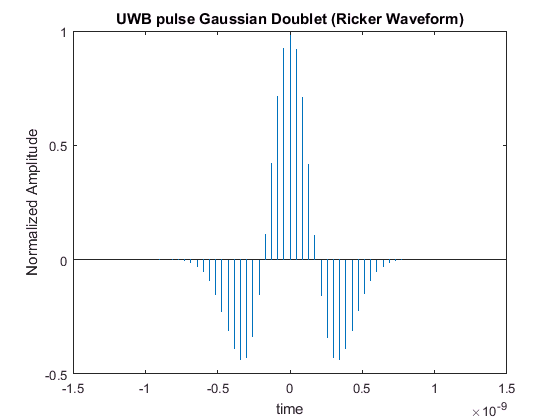

pulse = (1 - 2*beta) .* exp(-beta);

stem(t,pulse, 'Marker', 'None')
xlabel('time');ylabel('Normalized Amplitude');
title('UWB pulse Gaussian Doublet (Ricker Waveform)');

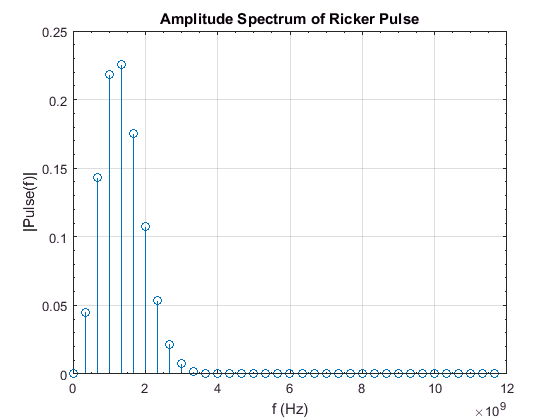


fftPulse = fft(pulse);
L = length(fftPulse);
P2 = fftPulse/L;
S_tx = P2(1:L/2+1);
S_tx(2:end-1) = 2*S_tx(2:end-1);

f = Fs*(0:(L/2))/L;
stem(f,abs(S_tx)) 
title('Amplitude Spectrum of Ricker Pulse')
xlabel('f (Hz)')
ylabel('|Pulse(f)|')
set(gca,'XMinorTick','on','YMinorTick','on');
grid on


% Using the Xethru Ultra Wideband Pulse
% center_freq = 8.748e9;
% tc = gauspuls('cutoff',center_freq,Bw/center_freq,[],-60); 
% t = -tc : 1/Fs : tc; 
% s_tx = gauspuls(t,center_freq,Bw/center_freq); 
% figure;
% plot(t,s_tx)
% 
% n = length(t);
% f = Fs*(-n/2:n/2-1)/n;
% S_tx = fftshift(fft(s_tx))/n;
% stem(f, abs(S_tx));
% 
% title('UWB Gaussian Pulse (Waveform)')
% xlabel('Time (s)')
% ylabel('Normalized Amplitude')

clear beta fftPulse Fs L P1 P2 pulse tao tc n

## Combination of Multiple Physiological Signatures

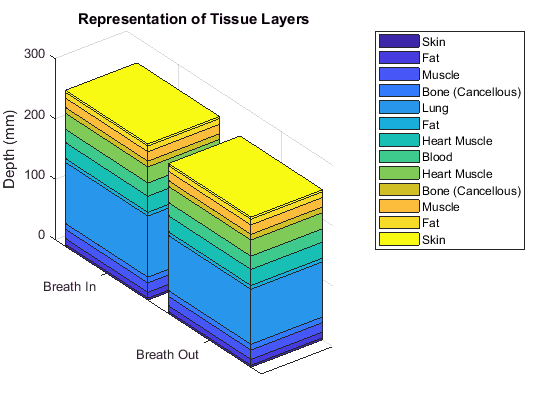

bodyLayer = {
    'Skin', 3.4;
    'Fat', 9.5;
    'Muscle', 15.6;
    'Bone (Cancellous)', 9.5;
    'Heart Muscle', 26.6;
    'Blood', 22;
    'Heart Muscle', 26.6;
    'Fat', 6.2;
    'Lung', 91.1;
    'Bone (Cancellous)', 9.5;
    'Muscle', 15.6;
    'Fat', 9.5;
    'Skin', 3.4;
    }; % mm

% Expansion coefficients
respExpansion = 10.0; %mm
cardiacExpansion = 1.0; %mm;

respIn = cell2mat(bodyLayer(:, 2)');
respIn(1,9) = respIn(1,9) + respExpansion;
respOut = cell2mat(bodyLayer(:, 2)');

% Draw a dielectric layer model from order
bar3(fliplr([respIn; respOut]),'stacked');

legend(flipud(bodyLayer(:,1)),'Location','northeastoutside')
title('Representation of Tissue Layers')
zlabel('Depth (mm)')
set(gca,'YTickLabel',["Breath In", "Breath Out"])


clear ph;

#  Calculating the overall reflection response


$$\Gamma_i \left(\omega \right)=\frac{\rho_i +\Gamma_{i+1} e^{-2{\mathrm{jk}}_i l_i } }{1+\rho_i e^{-2{\mathrm{jk}}_i l_i } }$$



$$\rho_i =\frac{1-\sqrt{\frac{\varepsilon_i }{\varepsilon_{i-1} }}}{1+\sqrt{\frac{\varepsilon_i }{\varepsilon_{i-1} }}}$$


where $\Gamma_i$ is the reflection reponse at the ith interface. Initialized by  $\Gamma_{m+1} =\rho_{m+1}$.

 $l_i$ is the thickness

${\text{k}}_i \left(\varepsilon ',\varepsilon \mathrm{''}\right)$is the propogation parameter (real and imaginary)

$n=\sqrt{\varepsilon_r }$  the refractive index

$k=\frac{2\pi n}{\lambda_0 }$ the propogation parameter

Relationship betwen refractive index and permittivity

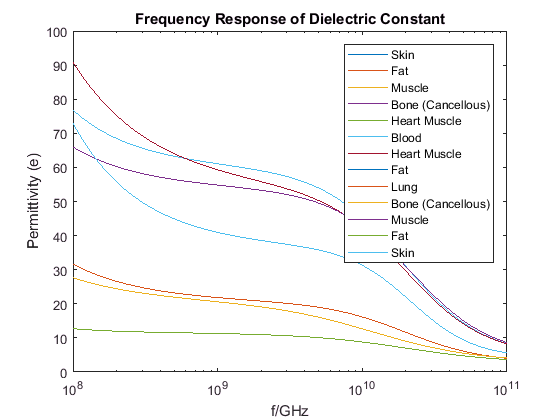

layer_count = length(bodyLayer);
freq = logspace(8,11);
e_w = zeros(layer_count+2, 50);
gamma = zeros(layer_count+1, 50);
p = zeros(layer_count+1, 50);

% Obtain frequency respones for all materials
figure(1);
cla;
for i=1:layer_count
    materialName = bodyLayer{i, 1};
    [p_inf, p_del, t_const, a, con] = get_material(materialName);
    e_w(i+1,:) = create_material(p_inf, p_del, t_const, a, con);
    
    semilogx(freq, real(e_w(i+1,:)));
    hold on;
end
hold off;
title('Frequency Response of Dielectric Constant');
xlabel('f/GHz');
ylabel('Permittivity (e)');
legend(bodyLayer{:, 1});

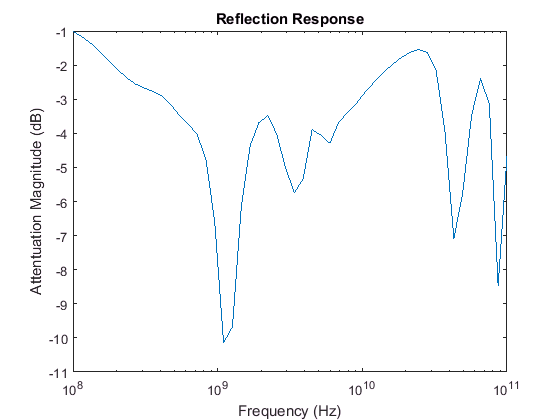


% First and last material is air
[p_inf, p_del, t_const, a, con] = get_material('Air');
e_w(1,:) = create_material(p_inf, p_del, t_const, a, con);
e_w(layer_count + 2,:) = e_w(1,:);

% Getting p
for i=1:layer_count+1
    p(i,:) = (1 - sqrt(e_w(i+1,:) ./ e_w(i,:))) ./ (1 + sqrt(e_w(i+1,:) ./ e_w(i,:)));
end

% Getting the refractive indexes and propogation constant (varies with frequency and layer)
n = e_w .^(0.5);
lambda = 3e8 ./ freq;
k = zeros(layer_count+2, 50);
for i = 1:length(n)
   k(:,i) = 2*pi*n(:, i) ./ lambda(i);
end

% Initialize del and p and then calculate gamma
gamma(layer_count+1,:) = p(layer_count+1,:);
l = cell2mat(bodyLayer(:, 2)) .* 1e-3; % Thickness of the layer
for i = layer_count:-1:1
    exponent = exp(-2i*k(i,:).*l(i));
    gamma(i,:) = (p(i,:) + gamma(i+1,:).*exponent) ./ (1 + p(i,:).*gamma(i+1,:).*exponent);
end

semilogx(freq, mag2db(abs(gamma(1,:))));

title('Reflection Response');
xlabel('Frequency (Hz)');
ylabel('Attentuation Magnitude (dB)');

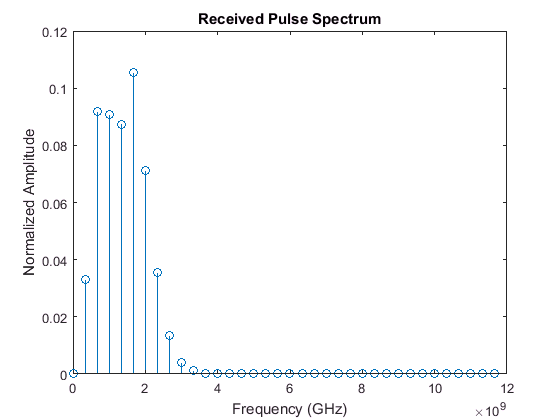


% Transfer Functions of Reciever, Transmiter
% We are assuming that the transfer functions
G = spline(freq, gamma(1,:), f);
S_rx = G.*S_tx;
title('Received Pulse Spectrum')
xlabel('Frequency (GHz)')
ylabel('Normalized Amplitude')

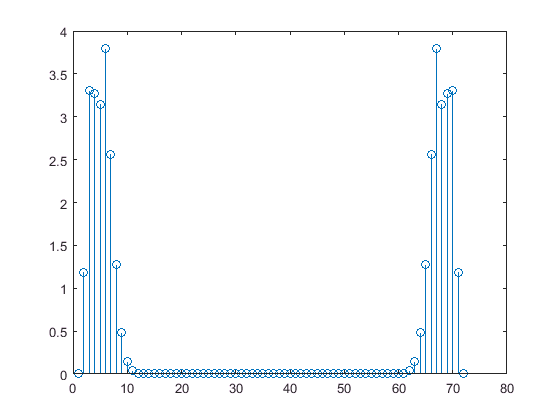


% Obtain the time domain from the Spectrum
s = S_rx ./ 2;
s = [s fliplr(s)];
L = length(s);
s = s * L;
stem(abs(s));

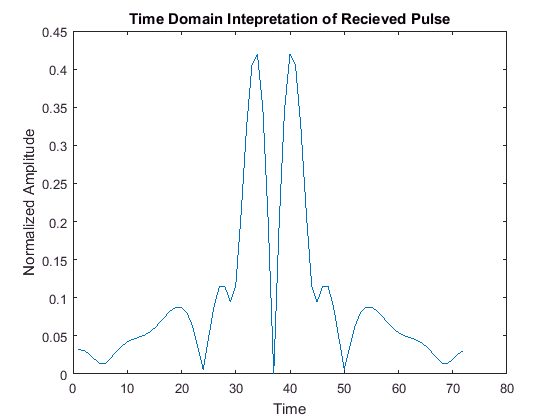

s_rx = ifft(s);

plot(abs(s_rx));

clear s
